clear;
clc;
hold on
qstart = [30 90];
qgoal = [90 50];
plot(qstart(:,1),qstart(:,2),'o')
plot(qgoal(:,1),qgoal(:,2),'o')
slop = (qgoal(2)-qstart(2))/(qgoal(1)-qstart(1))

slop =   -0.666666666666667


rotation = [cos(slop) sin(slop);sin(slop) cos(slop)];
R1(1,:) = [0 0];
R(1,:) = [0 0];
height = 100;
width = 100;
axis ([0 width 0 height]);
mu = [60 35];
sigma = [50 0;0 2]

sigma =     50     0
     0     2


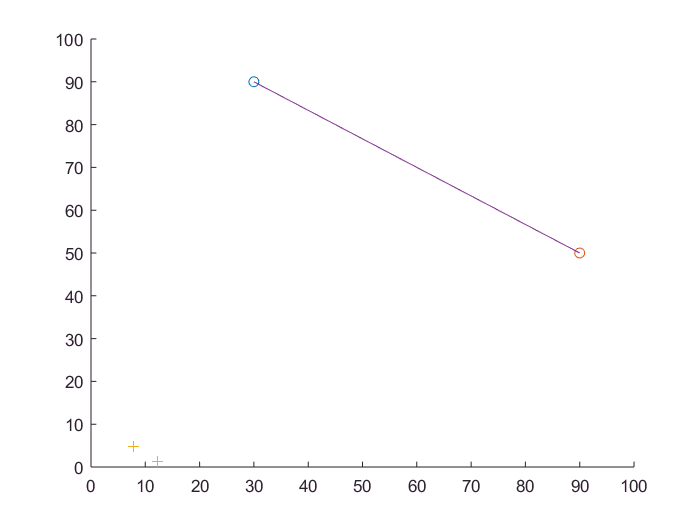


rng default  % For reproducibility
hold on
for i=1:50
R = mvnrnd(mu,sigma);
R1(i,:) = R*rotation;

end
plot(R1(:,1),R1(:,2),'+')
plot([qstart(1),qgoal(1)],[qstart(2),qgoal(2)])